s = tf('s');
%todos os dados estão em metros
a1 = 0.005;%area de secção tanque 1
a2 = 0.005;%area de secção tanque 2
g =  9.8;%gravidade
A1 = 0.4273; %Area tanque 1
A2 = 0.5184; %Area tanque 2
h1 = 0.09; %altura tanque 1 regime permanente
h2 = 0.06; %altura tanque 2 regime permanente
Kp = 10;
Ki = 0.5;
Kd = 0;
C = pid(Kp, Ki, Kd);
num = (a1*sqrt(2*g))+(s/A1); 
dem1 = s+(a1*sqrt(2*g))/(A1*sqrt(h1));
dem2 = s+(a2*sqrt(2*g))/A2*sqrt(h2);

G = num/(dem1*dem2);

G

G =
 
             s + 0.009459
  ----------------------------------
  0.4273 s^2 + 0.07826 s + 0.0007718
 
Continuous-time transfer function.
Model Properties


C

C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 10, Ki = 0.5
 
Continuous-time PI controller in parallel form.
Model Properties


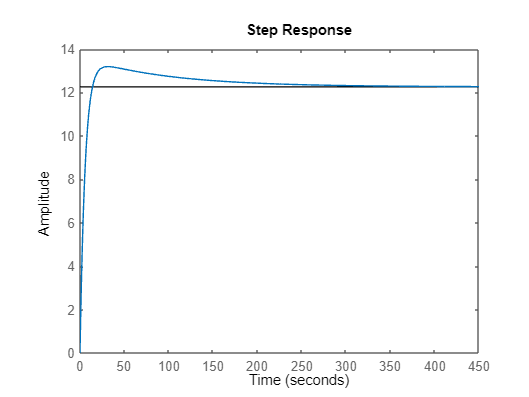

step(G)

feedback(C*G, 1)

ans =
 
          10 s^2 + 0.5946 s + 0.004729
  --------------------------------------------
  0.4273 s^3 + 10.08 s^2 + 0.5954 s + 0.004729
 
Continuous-time transfer function.
Model Properties


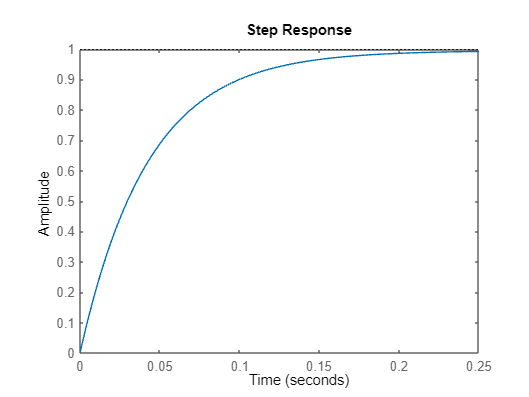

step(feedback(G*C,1))